# Customize Table Row Separators

To customize the lines that separate table rows, set the properties of an `mlreportgen.ppt.RowSep` object and add the object to the `Style` property of an `mlreportgen.ppt.Table` object. This example makes the row separators dashed and red with a line width of three points.

Create a presentation.

import mlreportgen.ppt.*
ppt = Presentation("myRowSep.pptx");
open(ppt);

Add a slide to the presentation.

slide = add(ppt,"Title and Table");

Create a table and set custom row separators.

t = Table(magic(3));
t.Style = [t.Style {RowSep("dash","red","3pt")}];

Add the title and table to the slide.

replace(slide,"Title","Table with custom row separators");
replace(slide,"Table",t);

Close and view the presentation.

close(ppt);
rptview(ppt);

Here is the table in the generated presentation:

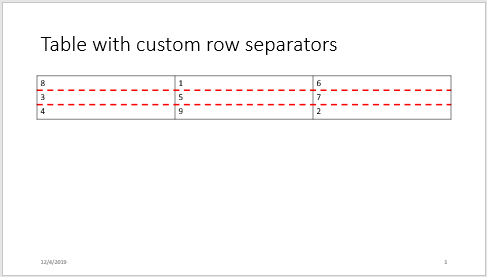

*Copyright 2019 The MathWorks, Inc.*